# Example 5a: Load and plot topography

Let's start by creating a mountain for our plane to fly by. We'll use Matlab's built-in peaks data for this, and we'll tweak the data set a little bit to set negative elevations to zero and rescale `X` and `Y` to larger dimensions. 

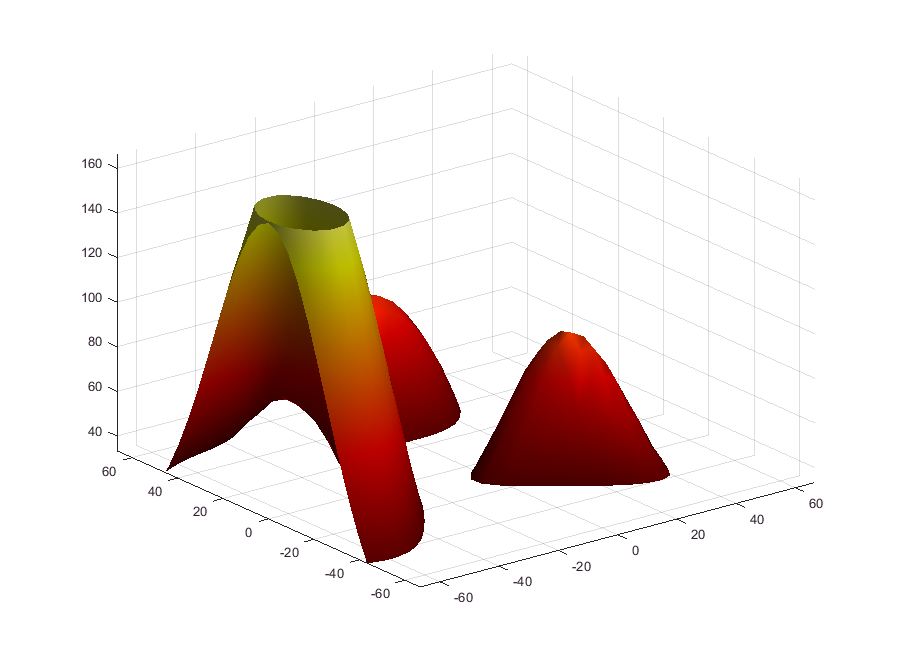

% Load and tweak peaks data:
[Y,X,Z] = peaks;
Z(Z<0)=0; 
X = flipud(X*35); 
Y = Y*35; 
Z = Z*25; 

% Plot peaks surface
figure('pos',[50 50 900 660])
hp = surf(X,Y,Z);
axis([-100 100 -100 100 0 200])
colormap(hot(256))
shading interp
lighting gouraud
camlight
zoom(1.5)
hold on

## Example 5b: Generate flight lines

Now our candycornesque landscape is plotted and we can create paths for airplanes. For this example, we'll scale the paths based on the number of frames we'll ultimately want in our movie show. 

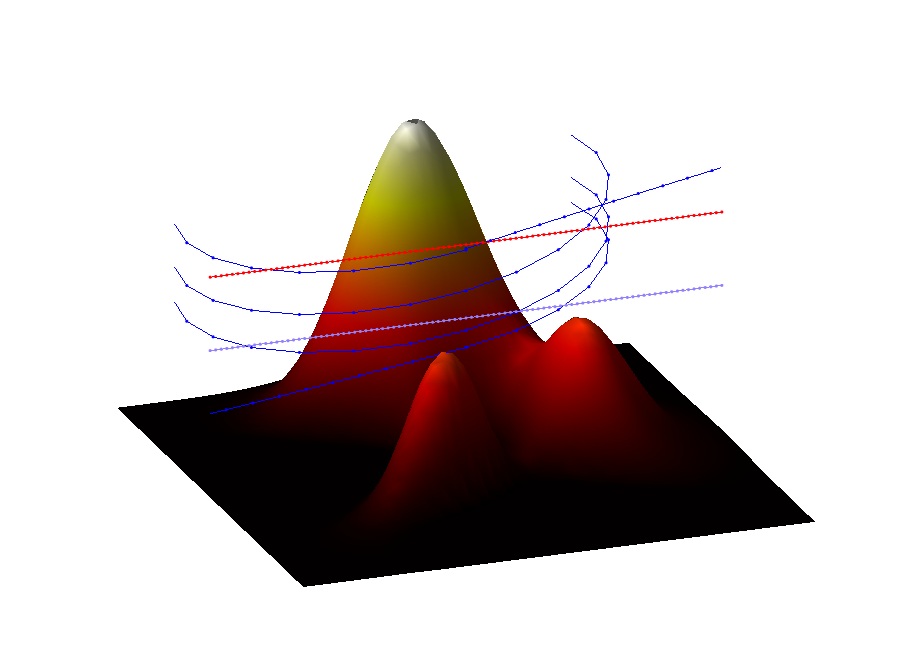

frames = 300; % number of frames in our movie show. 

% Plane 1: Periwinkle plane flies left to right: 
y1 = linspace(-250,400,frames); 
x1 = zeros(size(y1)); 
z1 = 100*ones(size(y1)); 
path1 = plot3(x1,y1,z1,'.-','color',[0.5569 0.5098 0.9961]);

% Plane 2: Red plane flies right to left: 
y2 = fliplr(y1); 
x2 = x1; 
z2 = z1+50; 
path2 = plot3(x2,y2,z2,'r.-');

% Plane 3: Gray and blue plane flies 'round the mountain: 
x3 = zeros(size(x2)); 
x3(201:273) = -80*sind((0:15:3*360)-90)-80;
y3 = zeros(size(x2)); 
y3(1:175) = -250; 
y3(176:200) = linspace(-250,0,25);
y3(201:273) = 80*cosd((0:15:3*360)-90);
y3(274:end) = linspace(0,250,length(y3)-273); 
z3 = 120+40*cos(linspace(pi,4*pi,length(y3)))+y3/4;
path3 = plot3(x3,y3,z3,'b.-');

% Set view: 
view([70 33])
axis([-100 100 -100 100 0 200])
grid off
set(gca,'color','none')
axis off

## Example 5c: Specify roll, pitch, and yaw

You can specify roll, pitch and yaw in a few different ways. In the case of airplane 2, which flies from right to left (in the negative y direction), a constant yaw value of -180 is appropriate. 

We can also make up values for roll, pitch, and yaw. Below, we add two barrel rolls starting at frame 185 for the red airplane. 

For more complex x,y,z paths, manually defining roll, pitch, and yaw can be a real exercise in bookkeeping. For those cases, we can use `xyz2rpy`, which does a mediocre job of it. Sometimes `xyz2rpy` underestimates or overestimates roll, so let's exaggerate the roll for plane 3 by a factor of 30: 

yaw2 = -180; % because the plane is flying toward -y
roll2 = zeros(size(y2)); 
roll2(185:210) = linspace(0,2*360,26); 

[roll3,pitch3,yaw3] = xyz2rpy(x3,y3,z3,30);

## Example 5d: Lights, camera

Now let's delete those flight paths and ready the camera. We'll also specify azimuth and elevation vectors for the camera. 

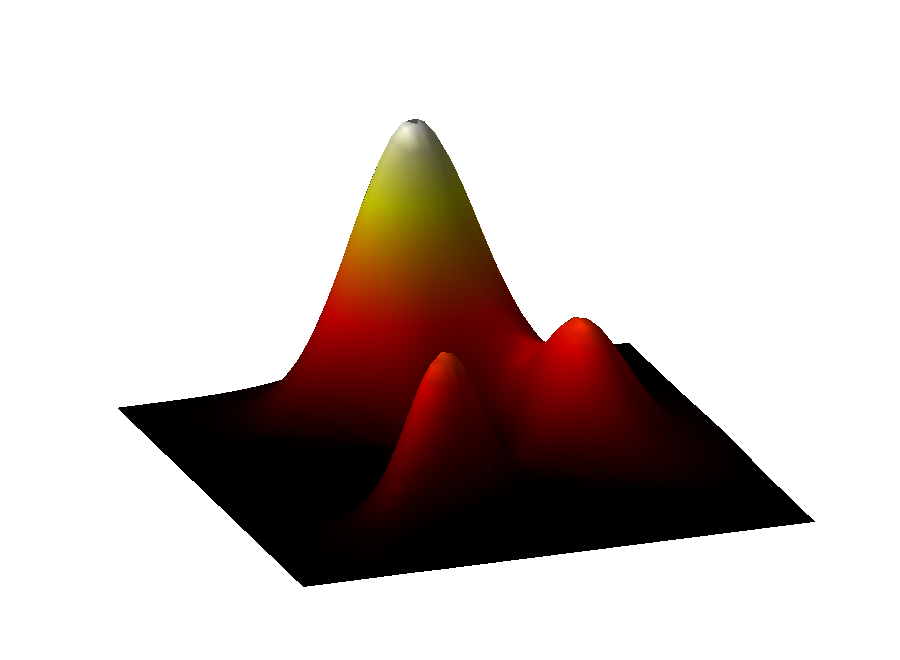

delete([path1 path2 path3])

az = linspace(70,85,frames); 
el = linspace(33,29,frames); 


writerObj = VideoWriter('c130_animation.avi')

writerObj =   VideoWriter

    General Properties:

       Filename:                 'c130_animation.avi'
       Path:                     '\\home-00-ah\sbachwan\Documents\Live Editor\Converted\3D plane'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                24
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


writerObj.FrameRate = 24;
open(writerObj);

## Example 5e: Animate

Now it's time to loop the animation.

%  for k = 1:frames
%      
%      % draw periwinkle plane: 
%      h1 = c130(x1(k),y1(k),z1(k),...
%          'color',[0.5569 0.5098 0.9961]); 
%      
%      % draw red plane: 
%      h2 = c130(x2(k),y2(k),z2(k),...
%          'roll',roll2(k),...
%          'yaw',yaw2,...
%          'color','red'); 
%      
%      % draw fancy plane: 
%      h3 = c130(x3(k),y3(k),z3(k),...
%          'lines','none',...
%          'wings','b',...
%          'tail','r',...
%          'roll',roll3(k),...
%          'pitch',pitch3(k),...
%          'yaw',yaw3(k));
%  
%      % set view and take a picture:
%      view([az(k) el(k)])
%      axis([-100 100 -100 100 0 200])
%      frame = export_fig(gcf,'-nocrop','-m2');
%      writeVideo(writerObj,frame);
%      
%      % delete the planes we just drew: 
%      delete([h1 h2 h3]); 
% %  end
% %  
% %  close(writerObj);